# DSP project

clc; clear; close all;

### Loading data and listening

[data, fs] = audioread('projectDSP.wav');
data = data - mean(data);
% sound(data, fs)

### spectrum analysis

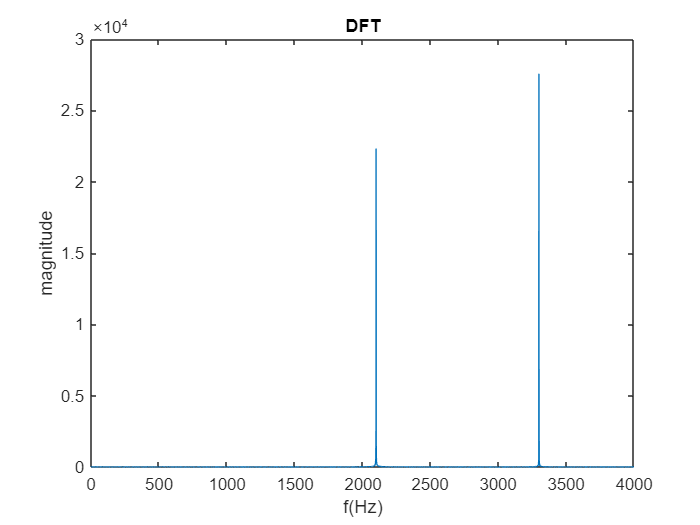

L = length(data);
f = fs * ( 0:floor(L/2)-1 ) / L ;   %frequency vector
t = (0:L-1)/fs ; % time vector
% single sided dft calculation
dft = abs(fft(data));
dft = dft(1:(L/2));
dft(2:end-1) = dft(2:end-1) * 2;

% plotting dft
figure("Name",'DFT')
plot(f,dft)
title('DFT')
xlabel('f(Hz)')
ylabel('magnitude')

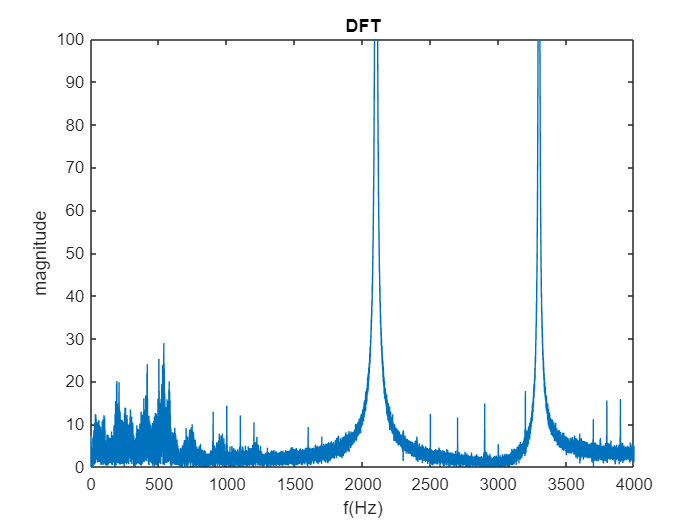


% in order to see more frequency detail
% we limit y axis
figure()
plot(f,dft)
title('DFT')
xlabel('f(Hz)')
ylabel('magnitude')
ylim([0 100])

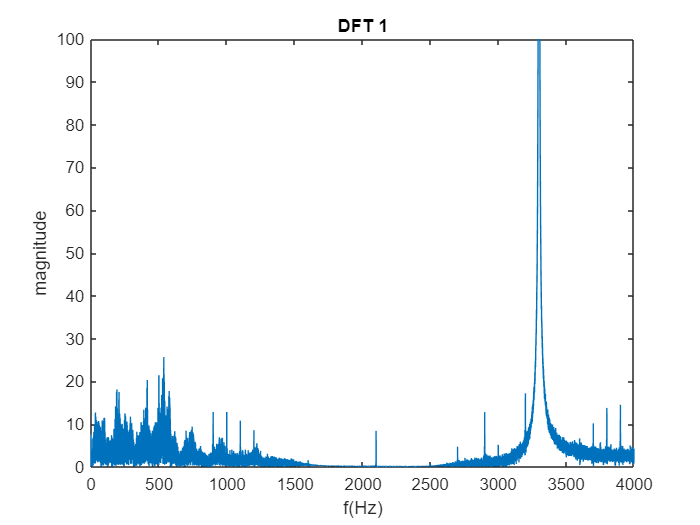



% first filter for peak around 2kHz
f1 = load('ham1.mat').Num;
data1 = conv(data, f1, "same"); %first filterred signal
for i=1:16
    data1 = conv(data1, f1, "same");
end
% DFT
dft1 = abs(fft(data1));
dft1 = dft1(1:(L/2));
dft1(2:end-1) = dft1(2:end-1) * 2;

figure()
plot(f, dft1)
title('DFT 1')
xlabel('f(Hz)')
ylabel('magnitude')
ylim([0 100])

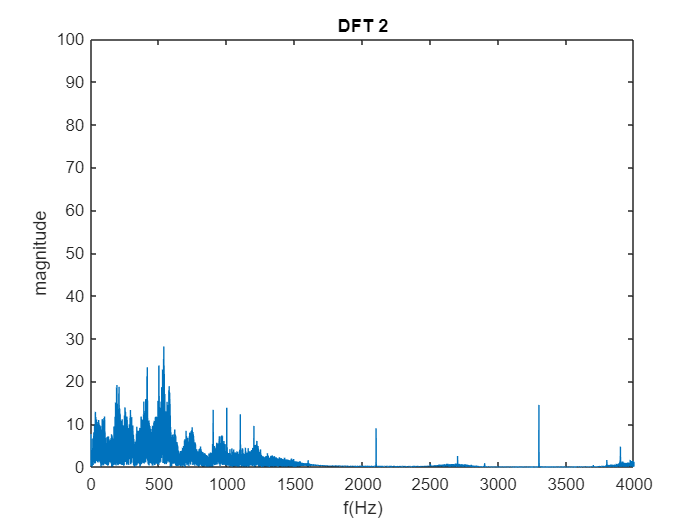


% audiowrite('1.wav', data1, fs)

% second filter for peak around 3.2kHz
f2  = load('ham2.mat').Num;
data2 = conv(data1, f2, "same"); %second filterred signal
for i=1:25
    data2 = conv(data2, f2, "same");
end

% DFT
dft2 = abs(fft(data2));
dft2 = dft2(1:(L/2));
dft2(2:end-1) = dft2(2:end-1) * 2;
figure()
plot(f, dft2)
title('DFT 2')
xlabel('f(Hz)')
ylabel('magnitude')
ylim([0 100])

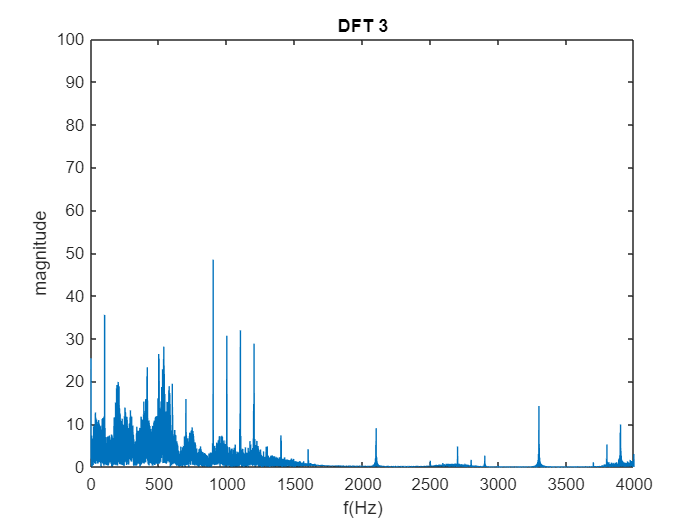


% weighted moving average
% h = [1/2 1/2];
% 
% data3 = 30 * (data2 - mean(data2));

%fading envelope
% fade_size = 20;
% fade = [linspace(0,1,fade_size)'; ones(L - 2*fade_size, 1); linspace(1,0,fade_size)'];
% data3 = data2 .* fade ;


% f3 = load('ham3.mat').Num;
% data3 = conv(data2, f3, 'same');
% for i=1:8
%     data3 = conv(data3, f3, 'same');
% end


fade_size = 5 ;
base = data2(50:3000);
n = length(base);
fade = [linspace(0,1,fade_size)'; ones(n - 2*fade_size, 1); linspace(1,0,fade_size)'];
base = base .* fade ;
bnoise = repmat(base,ceil(L/n) , 1);
bnoise = bnoise(1:L);

data3 = data2 - bnoise ;
% DFT
dft3 = abs(fft(data3));
dft3 = dft3(1:(L/2));
dft3(2:end-1) = dft3(2:end-1) * 2;

%fading envelope

fade_size = 100;
fade = [linspace(0,1,fade_size)'; ones(L - 2*fade_size, 1); linspace(1,0,fade_size)'];
data3 = data3 .* fade ;

figure()
plot(f, dft3)
title('DFT 3')
xlabel('f(Hz)')
ylabel('magnitude')
ylim([0 100])


gain = 30;  % amplifying 
data3 = data3 * gain;

% Wavelet denoising
wname = 'db4'; 
level = 10;  
data3 = wdenoise(data3, level,'wavelet', wname);

% sound(data4, fs)
% data3(abs(data3) < 0.2 ) = 0;
sound(data3, fs)
audiowrite("1.wav", data3, fs)

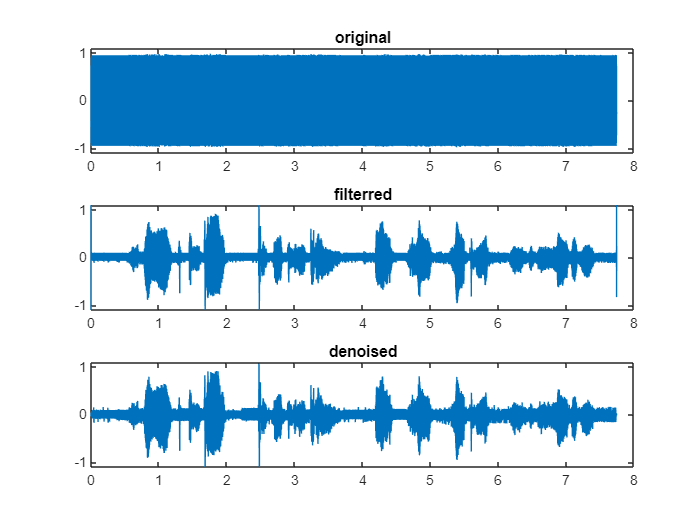


ymax = 1.1;

figure()
subplot(311)
plot(t, data)
title('original')
ylim([-ymax ymax])

subplot(312)
plot(t, gain *data2)
title('filterred')
ylim([-ymax ymax])

subplot(313)
plot(t, data3)
title('denoised')
ylim([-ymax ymax])